PathsDan = 'E:\Motorcycle\Data\MatLab\Mixail';
NameFile = 'FMixa.mat'

NameFile = 'FMixa.mat'

PathFile = PathsDan+"\"+NameFile

PathFile = "E:\Motorcycle\Data\MatLab\Mixail\FMixa.mat"

load('-mat', PathFile)
Acc = double(FMixa.AC_pwrAct(1:length(FMixa.AC_pwrAct)-2));


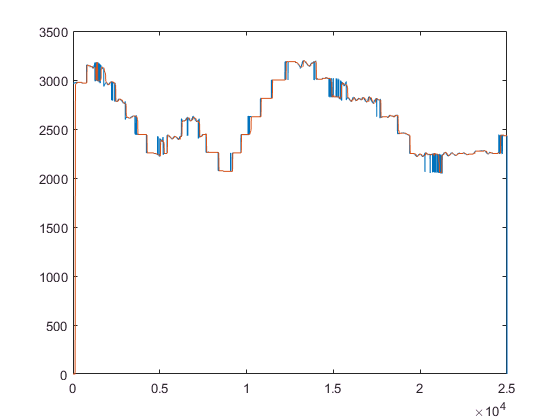

sig= SigmoidMixail(50);
Result= sig.CalcSignal(Acc);
t0=1:length(Acc);
%plot(Result.rez)
t0=1:length(Acc);
z=ema(Result.rezU, 5);
plot(t0, Acc, t0, z);

t0=1:length(Acc);
tAcc=zeros(length(Acc), 2);
tAcc(:,1)=t0';
tAcc(:,2)=Acc';


tAcc1(:,:)=tAcc(1:9600,:);

function z=ema(y, nCount)
    yCount=length(y);
    z=zeros(yCount, 1);
    z(1)=y(1);
    alfa=2/(nCount+1);
    alfa1=(1-alfa);
    for i=2:1:yCount
      z(i)=alfa*y(i)+alfa1* z(i-1); 
    end
end